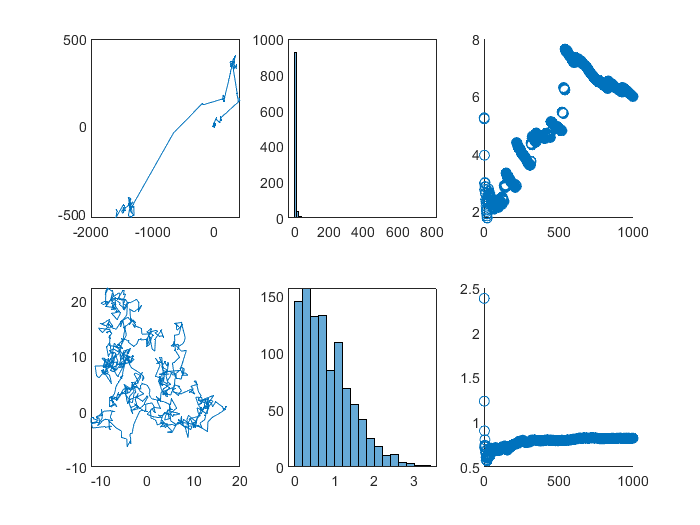

fullMatFileName = fullfile('C:\Users\KUBA\Desktop\semestr_6\KADD\Lab\lab11\dane1.csv');
s = load(fullMatFileName);
X1=s(1:1001);
Y1=s(1002:2002);
fullMatFileName = fullfile('C:\Users\KUBA\Desktop\semestr_6\KADD\Lab\lab11\dane2.csv');
s1 = load(fullMatFileName);
X2=s1(1:1001);
Y2=s1(1002:2002);
X=[];
for k = 1:1000
    Xn = sqrt((X1(k)-X1(k+1))^2+(Y1(k)-Y1(k+1))^2);
    X=[X,Xn];
end
XX=[];
for k = 1:1000
    Xn = sqrt((X2(k)-X2(k+1))^2+(Y2(k)-Y2(k+1))^2);
    XX=[XX,Xn];
end
j=linspace(0,1000,1000);
Y3=cumsum(XX(1:1000))./j;
X3=cumsum(X(1:1000))./j;
subplot(2,3,1);
plot(X1,Y1);
subplot(2,3,4);
plot(X2,Y2);
subplot(2,3,2);
h=histogram(X);
subplot(2,3,5);
h1=histogram(XX);
subplot(2,3,3);
scatter(j,X3)
subplot(2,3,6);
scatter(j,Y3)